# **Modelo SIR**

## **Cargando los datos iniciales**

Con los datos obtenidos se realiza la estimacion de los suceptibles actuales 

ReadData
Regresion
S_data = N - I_data - R_data;

dS_data = diff(S_data);
dI_data = diff(I_data);
dR_data = diff(R_data);

Regresión sobre los datos de ln(S) vs R

w_logSR = polyfit(R_data, log(S_data), 1);

reg_logSR = w_logSR(1)*R_data + w_logSR(2);

## Configuración de parametros 

Se establecen los valores de $\beta \;y\;\gamma$ encontrados anteriormente

%gamma = rmmissing(dR_data./I_data(1:end-1)); 
gamma = 0.53;
%sum(gamma)/length(gamma);

beta =0.58;
%-N*gamma*w_logSR(1);

vacunacion = true;

## Condiciones iniciales

Recuperados, Sucepetibles e Infectados en el dia cero del modelo.

R0 = 0;
S0 = exp(w_logSR(2));
I0 = N - S0;

%max 1-07-2021
dates_model =  dates(1):datetime('1-01-2021', 'InputFormat', 'dd-MM-yyyy');
T = 1:length(dates_model);


## Vacunación

Estimación usando la última tendencia del USD/COP el día 22 de Julio del 2020

compra de vacunas cada 30 días.

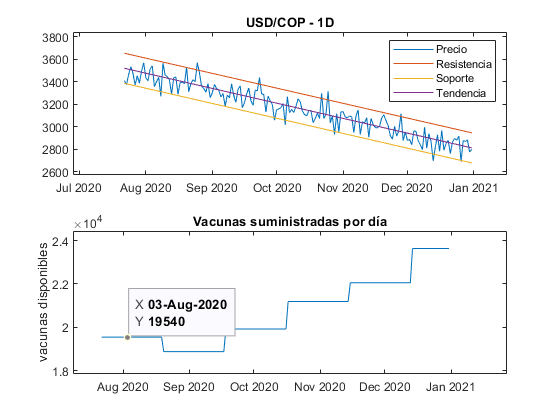

date_vac0 = 143;
   vacunas_dia = zeros(1, length(dates_model));
   
   if vacunacion 
          vacunas_dia(date_vac0+1:end) = vacunas(length(dates_model)-date_vac0);
   end   

[T, X] = ode45(@f, T, [S0; I0; R0]);

S = X(:, 1);
I = X(:, 2);
R = X(:, 3);

## Suceptibles

A continuación se muestran los graficos de suceptibles estimados por el modelo y la estimacion actual segun los datos oficiales

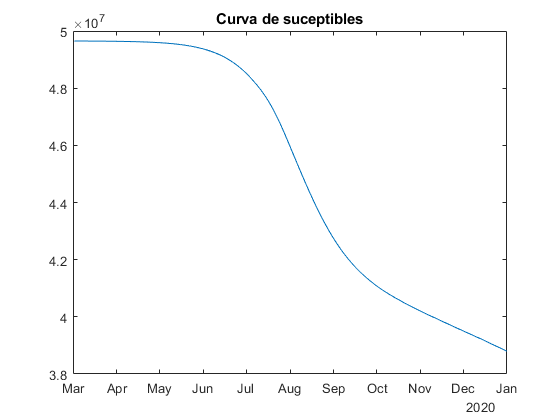

%{
figure
subplot(2, 1, 1)
plot(dates_model, S);
subplot(2, 1, 2)
plot(dates_model, S);
hold on
plot(dates, S_data, 'o');
ylim([min(S_data) max(S_data)])
%}

figure
plot(dates_model, S);
title('Curva de suceptibles')

## Curvas de Infectados

A continuación se muestran los graficos de infectados activos estimados por el modelo y la estimacion actual segun los datos oficiales

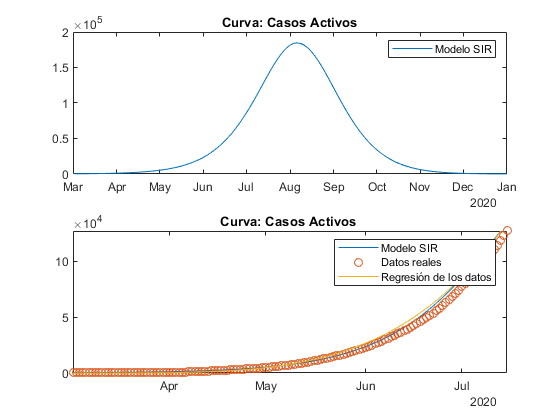

figure('Name', 'Curvas de Infectados')
subplot(2, 1, 1)
plot(dates_model, I);
legend('Modelo SIR');
title('Curva: Casos Activos')
subplot(2, 1, 2)
plot(dates_model, I);
hold on
plot(dates, I_data, 'o');
hold on
plot(dates, reg_I);

legend('Modelo SIR', 'Datos reales', 'Regresión de los datos');
title('Curva: Casos Activos ')
ylim([min(I_data) max(I_data)]);
xlim([dates(1) dates(end)])

## Curvas de Recuperados

A continuación se muestran los graficos de recuperados estimados por el modelo y la estimacion actual segun los datos oficiales

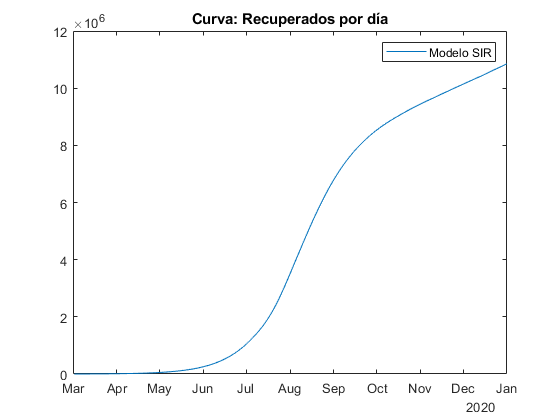

%{
figure
subplot(2, 1, 1)
plot(dates_model, R);
legend('Modelo SIR');
title('Curva: Recuperados por día')
subplot(2, 1, 2)
plot(dates_model, R);
hold on
plot(dates, R_data, 'o');
hold on
plot(dates, reg_R);
legend('Modelo SIR', 'Datos reales', 'Regresión de los datos');
title('Curva: Recuperados por día')
ylim([min(R_data) max(R_data)]);
xlim([dates(1) dates(end)])
%}

figure
plot(dates_model, R);
legend('Modelo SIR');
title('Curva: Recuperados por día')

## Modelo SIR 

A continuación se muestran los graficos del modelo resumiendo la actividad diaria y los cambios en la población

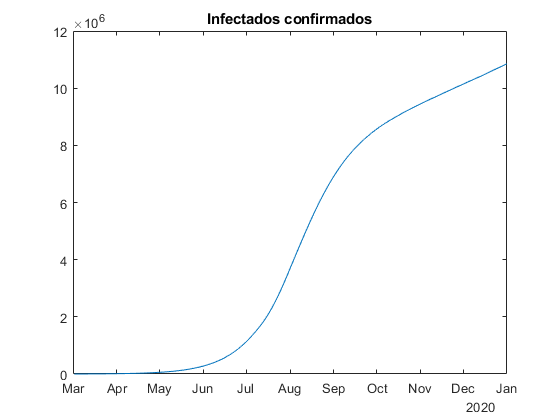

figure
plot(dates_model, N - S)
title('Infectados confirmados')

## Gráficas de la regresión

A continuación se presenta en detalle las regresiones calculadas vs los datos actuales

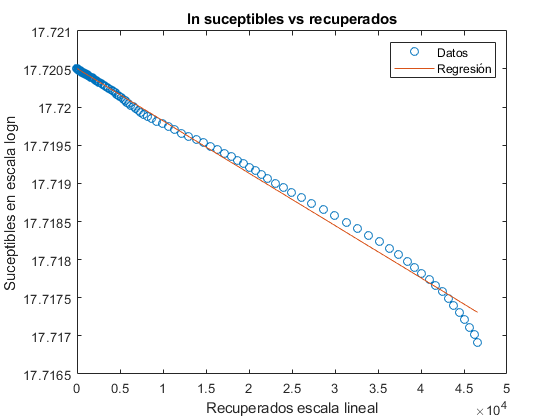

figure
plot(R_data, log(S_data), 'o')
hold on
plot(R_data, reg_logSR)
title('log suceptibles vs recuperados')
legend('Datos', 'Regresión')
ylabel('Suceptibles en escala logn')
xlabel('Recuperados escala lineal')

## Calculo de $\beta \;y\;\gamma$

bet = 0:0.01:1;
gam = 0:0.01:1;

err = zeros(length(bet), length(gam));

### **Funcion error **

Se usa para aproximar los parametros iniciales calculando el error relativo de las regresiones contra el modelo calculado con las variaciones de los parametros

for i = 1:length(bet)
    for j = 1:length(gam)
        beta = bet(i);
        gamma = gam(j);
        
        [T, Y] = ode45(@f, T, [S0; I0; R0]);
       
        err(i, j) = error(reg_I, Y(:, 2)', t);%(error(reg_I, Y(:, 2)', t) + error(S_data', Y(:, 1)', t) + error(reg_R, Y(:, 3)', t) )/3;
    end
end
clear Y i j

minimo_columnas = min(err);
minimo = min(minimo_columnas);

col = find(minimo_columnas == minimo);
fil = find(err(:, col) == minimo);

clear minimo_columnas minimo

bet(fil)

ans = 0.5800

gam(col)

ans = 0.5300


clear col fil

## Función Modelo SIR

function dX = f(t, X)
    S = X(1);
    I = X(2);
    R = X(3);
    gamma = evalin('base', 'gamma');
    beta = evalin('base', 'beta');
    N = evalin('base', 'N');  
    vacunas_dia = evalin('base', 'vacunas_dia');   
    
    
    
    dX = [-beta*S.*(I/N) - vacunas_dia(floor(t));...
           beta*S.*(I/N) - gamma*I;...
            gamma*I + vacunas_dia(floor(t))];
   
end